3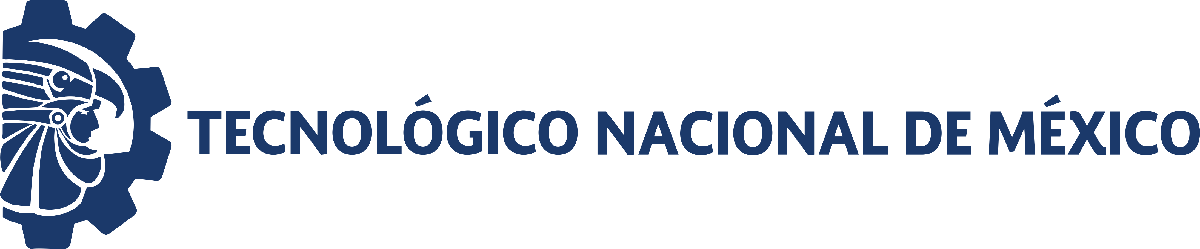                                 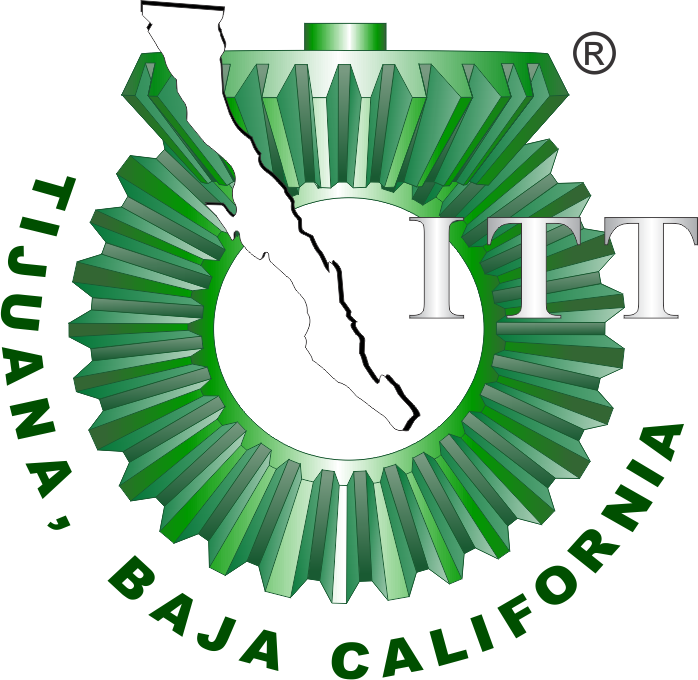

# Práctica tres: Modelado y control del sistema musculoesquelético

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

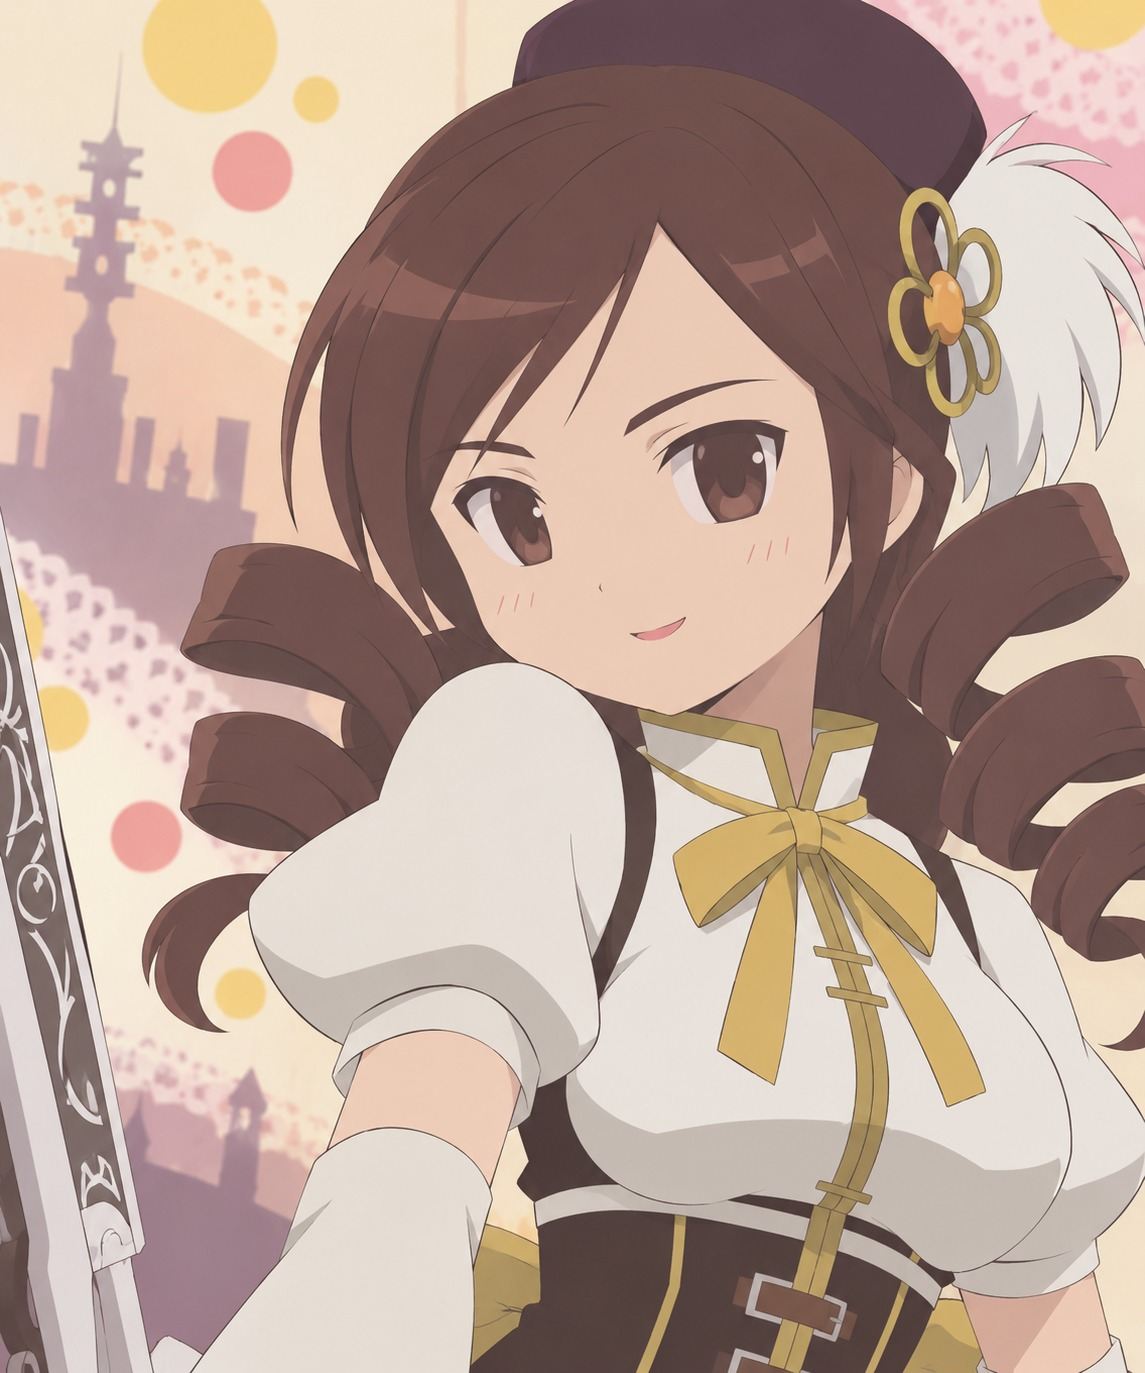

Nombre del alumno:** Judith Valeria Soriano Angeles**

Número de control:** 23212231**

Correo institucional:** 23212231@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; close all; warning('off','all')
open_system("Sistema");
parameters.StopTime = "10";
parameters.Solver = 'ode15s';
parameters.MaxStep = '1E-3';

## Respuesta al Impulso Unitario

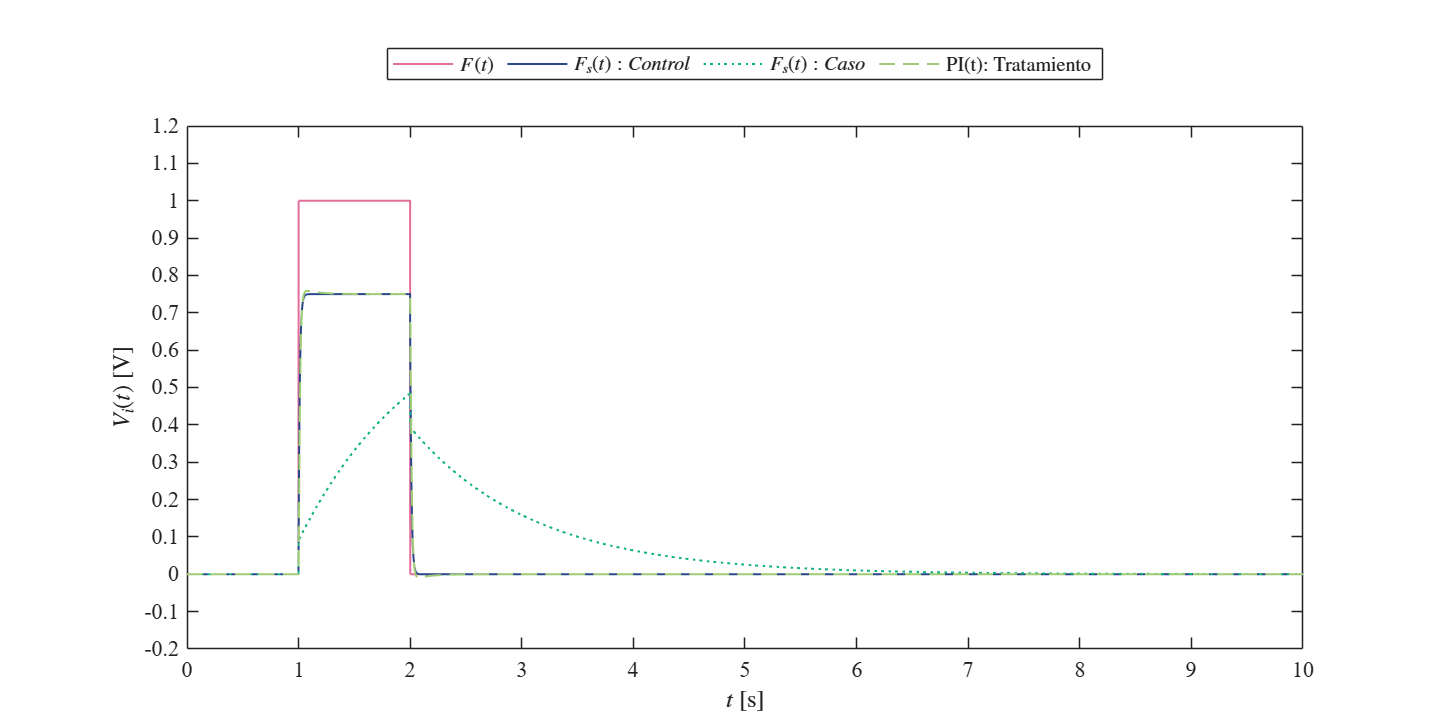

X = sim('Sistema',parameters);
plotsignals(X.t,X.F,X.Fsx,X.Fsy,X.PID,'Caso')

## Función: Respuesta de la simulación

function plotsignals(t,F,Fsx,Fsy,PID,signal)
    set(figure(),'color','w')
    set(gcf,'units','inches','position', [1,1,10,5])
    set(gca, 'fontname','times new roman','fontsize',11)
    hold on; grid off; box on;
    clr1 = [227, 109, 155] / 255; %rosa
    clr2 = [43, 71, 137] / 255; %azul
    clr3 = [16, 177, 131] / 255; %verde oscuro 
    clr4 =  [160, 203, 117] / 255; %verde claro
    order = [clr1;clr2;clr3;clr4]; colororder(order)

    plot(t,F,'-',t,Fsx,'-',t,Fsy,':',t,PID,'--','LineWidth',1,'MarkerSize',5,'MarkerIndices',...
        1:1e3:length(t));
    L=legend('$F(t)$', '$F_{s}(t): Control$','$F_s(t): Caso$','PI(t): Tratamiento$');
    set(L,'interpreter','latex','location','northoutside','orientation','horizontal');
    xlabel('$t$ [s]','Interpreter','latex')
    ylabel('$V_i(t)$ [V]', 'Interpreter','latex')
    xlim([0 10]); xticks(0:1:10);
    ylim([-0.2 1.2]); yticks(-0.2:0.1:1.2);
   
    exportgraphics(gcf,[signal, '_matlab.pdf'],'contenttype','vector')

end